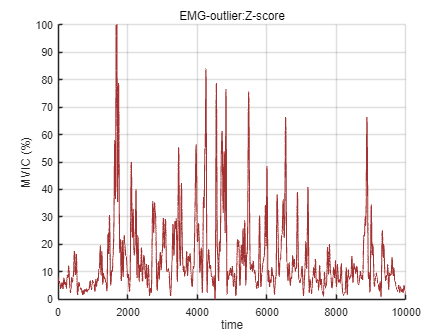

%1) 데이터 받아오기
time=out.time.Data; %실험 시 저장한 'out' SimulationOutput 작업 공간에 저장
data = [time,double(squeeze(out.TA.Data))];
data2 = [time,double(squeeze(out.GC.Data))];
% [acc_thigh_x, acc_thigh_y, acc_thigh_z] = deal(squeeze(acc_thigh(1, :, :)), squeeze(acc_thigh(2, :, :)), squeeze(acc_thigh(3, :, :)));
% [acc_shank_x, acc_shank_y, acc_shank_z] = deal(squeeze(acc_shank(1, :, :)), squeeze(acc_shank(2, :, :)), squeeze(acc_shank(3, :, :)));
% [gyro_thigh_x, gyro_thigh_y, gyro_thigh_z] = deal(squeeze(gyro_thigh(1, :, :)), squeeze(gyro_thigh(2, :, :)), squeeze(gyro_thigh(3, :, :)));
% [gyro_shank_x, gyro_shank_y, gyro_shank_z] = deal(squeeze(gyro_shank(1, :, :)), squeeze(gyro_shank(2, :, :)), squeeze(gyro_shank(3, :, :)));

%2) emg 데이터 필터링
num=1;
time=data(num:end,1);
emg=data(num:end,2);
emg=abs(emg-mean(emg)); %영점 조절: axis 조정

emg2=data2(num:end,2);
emg2=abs(emg2-mean(emg2));

time=interp1(1:length(time),time, linspace(1,length(time),10000),'linear');

%3) data 보간 및 MVC normalization 수행
Fs = 100; 
order = 4; 
cutoff = 6; 
[b, a] = butter(order, cutoff/(Fs/2));

emg_bw = filtfilt(b, a, emg); 
emg_bw2 = filtfilt(b, a, emg2); 

emg_bw=interp1(1:length(emg_bw),emg_bw, linspace(1,length(emg_bw),10000),'linear')';
emg_bw2=interp1(1:length(emg_bw2),emg_bw2, linspace(1,length(emg_bw2),10000),'linear')';

emg_MVC = mean([10]);
emg_bw = ((emg_bw)/ (emg_MVC)*100); 

emg_MVC2 = mean([18]); 
emg_bw2 = ((emg_bw2)/ (emg_MVC2)*100); 

%1) outlier: Q1-Q3 
% Q1 = quantile(emg_bw, 0.25);
% Q3 = quantile(emg_bw, 0.75);
% IQR = Q3 - Q1;
% emg_bw_filtered= emg_bw(emg_bw >= (Q1 - 1.5 * IQR) & emg_bw <= (Q3 + 1.5 * IQR));

%2) Z-score
% z_scores = (emg_bw - mean(emg_bw)) / std(emg_bw);
% emg_bw_filtered = emg_bw(abs(z_scores) <= 2);
% 
% z_scores = (emg_bw2 - mean(emg_bw2)) / std(emg_bw2);
% emg_bw2_filtered = emg_bw2(abs(z_scores) <= 2);


figure;
hold on;
%plot(UDP_data,  'Color', [150/255, 150/255, 150/255], 'LineWidth', 5);
plot(emg_bw, 'Color', [165/255, 50/255, 50/255], 'LineWidth', 1);
%plot(emg_bw_filtered, 'Color', [235/255, 120/255,120/255], 'LineWidth', 1);
xlabel('time');
ylabel('MVIC (%)');
title('EMG-outlier:Z-score');
grid on
xlim([0, 10000]);
ylim([0, 100]);
hold off;

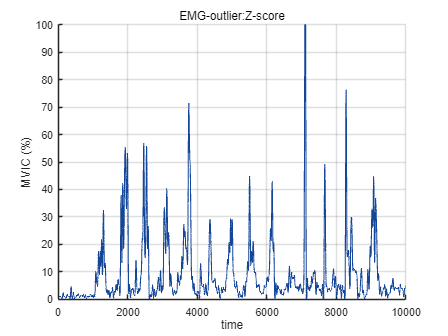


figure;
hold on;
plot(emg_bw2, 'Color', [20/255, 70/255, 153/255], 'LineWidth', 1);
%plot(emg_bw2_filtered, 'Color', [90/255, 150/255, 223/255], 'LineWidth', 1);
xlabel('time');
ylabel('MVIC (%)');
title('EMG-outlier:Z-score');
%legend('level','TA','GC')
grid on
xlim([0, 10000]);
ylim([0, 100]);
hold off;


%4 -1) 보행 환경에 따른 데이터 분류 위해 zero-crossing 찾기
% gyro_thigh_z_interp=interp1(1:length(gyro_shank_z),gyro_shank_z, linspace(1,length(gyro_shank_z),10000),'linear');
% point=find(diff(sign(gyro_thigh_z_interp))~=0);
% 
% figure;
% plot(gyro_thigh_z_interp, 'Color', [77/255, 150/255, 255/255], 'LineWidth', 2);
% hold on;
% plot(point, gyro_thigh_z_interp(point), 'ro');
% xlabel('Index');
% ylabel('Value');

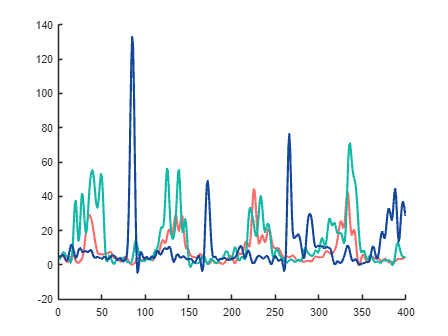

%4 - 2) 보행 환경에 따른 데이터 분류 
idx=  [1690,4155,6560,9160] ;% !!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!수정 필요

env = {'IC', 'LG', 'DC','IC_2',  'LG_2', 'DC_2'};

sections = {'IC',  'LG', 'DC'};
sections2 = {'IC_2',  'LG_2', 'DC_2'};

for i = 1:length(sections)
    eval([sections{i} ' = emg_bw(idx(i):idx(i + 1) - 1, :);']);
    eval([sections2{i} ' = emg_bw2(idx(i):idx(i + 1) - 1, :);']);
end

%4-3) 각 gait cycle 별로 분류
interpolate_data(env, 400);%!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!!수정 필요
% for i = 1:length(env)
%     eval([env{i} ' = reshape(' env{i} ', 100, 4);']);%!!!!!!!!!!!!!!!!!!!!!!!!!!수정 필요
% end
figure;
hold on;
plot(LG_2,  'Color',[255/255, 107/255, 107/255], 'LineWidth', 2);%red
plot(IC_2, 'Color',[15/255, 185/255, 165/255], 'LineWidth', 2); %green
plot(DC_2, 'Color', [20/255, 70/255, 153/255], 'LineWidth', 2); %blue
hold off;

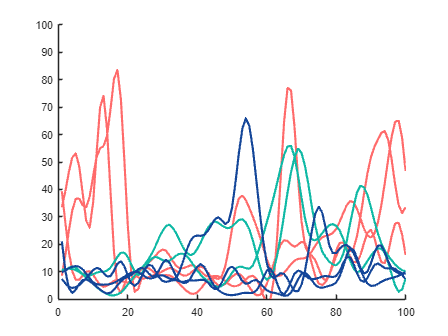

[lg, ic, dc, lg_2,ic_2,dc_2] = deal(zeros(100, 4));

idx= [1,100,240,310,400];
for i =1:length(idx)-1
    a=IC(idx(i):idx(i+1));
    a2=IC_2(idx(i):idx(i+1));
    ic(:,i)=interp1(1:length(a),a, linspace(1,length(a),100),'linear')';
    ic_2(:,i)=interp1(1:length(a2),a2, linspace(1,length(a2),100),'linear')';
end

idx=[1,100,205,310,400];
for i =1:length(idx)-1
    a=LG(idx(i):idx(i+1));
    a2=LG_2(idx(i):idx(i+1));
    lg(:,i)=interp1(1:length(a),a, linspace(1,length(a),100),'linear')';
    lg_2(:,i)=interp1(1:length(a2),a2, linspace(1,length(a2),100),'linear')';
end


idx=[1,100,200,310,400];
for i =1:length(idx)-1
    a=DC(idx(i):idx(i+1));
    a2=DC_2(idx(i):idx(i+1));
    dc(:,i)=interp1(1:length(a),a, linspace(1,length(a),100),'linear')';
    dc_2(:,i)=interp1(1:length(a2),a2, linspace(1,length(a2),100),'linear')';
end
ic(:,2)=[];
ic_2(:,2)=[];
ic(:,1)=[];
ic_2(:,1)=[];
lg(:,3)=[];
lg_2(:,3)=[];
dc(:,1)=[];
dc_2(:,1)=[];

figure;
hold on;
plot(lg,  'Color',[255/255, 107/255, 107/255], 'LineWidth', 2);%red
plot(ic, 'Color',[15/255, 185/255, 165/255], 'LineWidth', 2); %green
plot(dc, 'Color', [20/255, 70/255, 153/255], 'LineWidth', 2); %blue
hold off;
ylim([0,100])

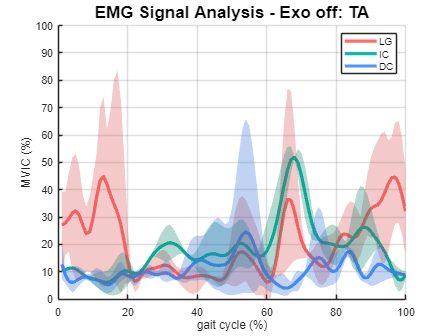



% 4-4) Average Plotting
figure;
hold on;

plot(mean(lg,2), 'Color', [255/255, 107/255, 107/255], 'LineWidth', 3); %red
plot(mean(ic,2), 'Color',[15/255, 185/255, 165/255], 'LineWidth',3); %green
plot(mean(dc,2), 'Color', [77/255, 150/255, 255/255], 'LineWidth', 3); %blue

plot_shade(lg, [215/255, 77/255, 77/255]); %r
plot_shade(ic, [5/255, 130/255, 110/255]); %g
plot_shade(dc, [47/255, 110/255, 215/255]); %b

xlabel('gait cycle (%)');
ylabel('MVIC (%)');
title('EMG Signal Analysis - Exo off: TA','FontSize',16,'FontWeight','bold');
legend('LG','IC','DC')

grid on
ylim([0, 100]);
hold off;

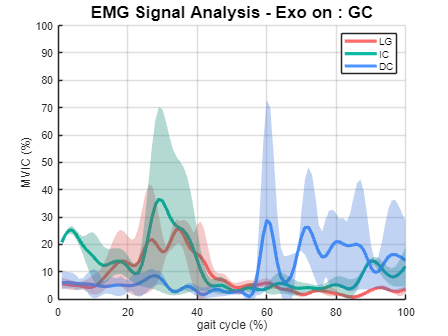


figure;
hold on;

plot(mean(lg_2,2), 'Color', [255/255, 107/255, 107/255], 'LineWidth', 3); %red
plot(mean(ic_2,2), 'Color',[15/255, 185/255, 165/255], 'LineWidth',3); %green
plot(mean(dc_2,2), 'Color', [77/255, 150/255, 255/255], 'LineWidth', 3); %blue


plot_shade(lg_2, [215/255, 77/255, 77/255]); %r
plot_shade(ic_2, [5/255, 130/255, 110/255]); %g
plot_shade(dc_2, [47/255, 110/255, 215/255]); %b

xlabel('gait cycle (%)');
ylabel('MVIC (%)');
title('EMG Signal Analysis - Exo on : GC','FontSize',16,'FontWeight','bold');
legend('LG','IC','DC')
grid on
ylim([0, 100]);
hold off;

exo_no=struct('LG',lg,'IC',ic,'DC',dc,'LG_2',lg_2,'IC_2',ic_2,'DC_2',dc_2)

exo_no = 다음 필드를 포함한 struct :
      LG: [100×3 double]
      IC: [100×2 double]
      DC: [100×3 double]
    LG_2: [100×3 double]
    IC_2: [100×2 double]
    DC_2: [100×3 double]


LG=[max(mean(exo_no.LG,1)), min(mean(exo_no.LG,1)), max(mean(exo_off.LG,1)), min(mean(exo_off.LG,1)),max(mean(exo_on.LG,1)), min(mean(exo_on.LG,1))]'

LG =    26.1100
   17.3691
   17.7865
    9.5295
   16.2246
    8.8281


IC=[max(mean(exo_no.IC,1)), min(mean(exo_no.IC,1)),max(mean(exo_off.IC,1)), min(mean(exo_off.IC,1)),max(mean(exo_on.IC,1)), min(mean(exo_on.IC,1))]'

IC =    19.9245
   16.9583
   16.5198
   13.9503
    9.8387
    9.7348


DC=[max(mean(exo_no.DC,1)), min(mean(exo_no.DC,1)),max(mean(exo_off.DC,1)), min(mean(exo_off.DC,1)),max(mean(exo_on.DC,1)), min(mean(exo_on.DC,1))]'

DC =    16.2604
    7.9620
   16.4431
   10.2175
   13.8553
    9.5057


LG_2=[max(mean(exo_no.LG_2,1)), min(mean(exo_no.LG_2,1)), max(mean(exo_off.LG_2,1)), min(mean(exo_off.LG_2,1)),max(mean(exo_on.LG_2,1)), min(mean(exo_on.LG_2,1))]'

LG_2 =     9.0296
    6.4812
    9.8864
    6.4947
    5.2980
    4.5266


IC_2=[max(mean(exo_no.IC_2,1)), min(mean(exo_no.IC_2,1)),max(mean(exo_off.IC_2,1)), min(mean(exo_off.IC_2,1)),max(mean(exo_on.IC_2,1)), min(mean(exo_on.IC_2,1))]'

IC_2 =    15.8810
    7.5416
   10.8320
   10.4805
    5.0970
    4.2968


DC_2=[max(mean(exo_no.DC_2,1)), min(mean(exo_no.DC_2,1)),max(mean(exo_off.DC_2,1)), min(mean(exo_off.DC_2,1)),max(mean(exo_on.DC_2,1)), min(mean(exo_on.DC_2,1))]'

DC_2 =    11.8799
    6.9253
   10.1422
    5.9363
    7.7276
    5.5051


[mean(mean(exo_no.LG,2)),std(mean(exo_no.LG,2)),mean(mean(exo_off.LG,2)),std(mean(exo_off.LG,2)),mean(mean(exo_on.LG,2)),std(mean(exo_on.LG,2))]

ans =    20.6296   11.5640   12.7699    5.0239   13.2208    3.4266


[mean(mean(exo_no.IC,2)),std(mean(exo_no.IC,2)),mean(mean(exo_off.IC,2)),std(mean(exo_off.IC,2)),mean(mean(exo_on.IC,2)),std(mean(exo_on.IC,2))]

ans =    18.4414    9.9168   15.2351   12.7726    9.7868   10.1186


[mean(mean(exo_no.DC,2)),std(mean(exo_no.DC,2)),mean(mean(exo_off.DC,2)),std(mean(exo_off.DC,2)),mean(mean(exo_on.DC,2)),std(mean(exo_on.DC,2))]

ans =    10.7514    4.2553   12.3427   10.9314   12.0930    4.8124



[mean(mean(exo_off.IC_2,2)-mean(exo_on.IC_2,2)),std(mean(exo_off.IC_2,2)-mean(exo_on.IC_2,2))]

ans =     5.9594    6.8035



[mean(mean(exo_no.LG_2,2)),std(mean(exo_no.LG_2,2)),mean(mean(exo_off.LG_2,2)),std(mean(exo_off.LG_2,2)),mean(mean(exo_on.LG_2,2)),std(mean(exo_on.LG_2,2))]

ans =     7.8801    6.6102    8.5107    4.0441    4.8706    1.2145


[mean(mean(exo_no.IC_2,2)),std(mean(exo_no.IC_2,2)),mean(mean(exo_off.IC_2,2)),std(mean(exo_off.IC_2,2)),mean(mean(exo_on.IC_2,2)),std(mean(exo_on.IC_2,2))]

ans =    11.7113    8.8306   10.6563    5.9970    4.6969    1.6992


[mean(mean(exo_no.DC_2,2)),std(mean(exo_no.DC_2,2)),mean(mean(exo_off.DC_2,2)),std(mean(exo_off.DC_2,2)),mean(mean(exo_on.DC_2,2)),std(mean(exo_on.DC_2,2))]

ans =     9.9737    7.3497    7.6248    3.4077    6.4063    2.1865


function interpolate_data(data_names, num_points)
    % 데이터 보간 함수
    % data_names: 변수 이름을 담고 있는 셀 배열
    % num_points: 보간 후의 데이터 포인트 수
    
    for i = 1:length(data_names)
        % 원본 데이터 가져오기
        data = evalin('base', data_names{i});
        
        % 보간
        interpolated_data = interp1(1:numel(data), data, linspace(1, numel(data), num_points), 'linear');
        
        % 변수 업데이트
        assignin('base', data_names{i}, interpolated_data);
    end
end

function plot_shade(data, color)
    % 데이터의 평균과 최소, 최대 값을 계산
    mean_data = mean(data, 2);
    min_data = min(data, [], 2);
    max_data = max(data, [], 2);
    
    % x축 데이터 정의
    x = 1:length(mean_data);

    % 쉐이딩 플롯
    fill([x fliplr(x)], [min_data' fliplr(max_data')], color, 'FaceAlpha', 0.3, 'EdgeColor', 'none');
end